%% TO see the output of the code you need to click on Run and then the whole output is shown
vidReader = VideoReader('video.mp4');   

opticFlow = opticalFlowLK('NoiseThreshold',0.009);

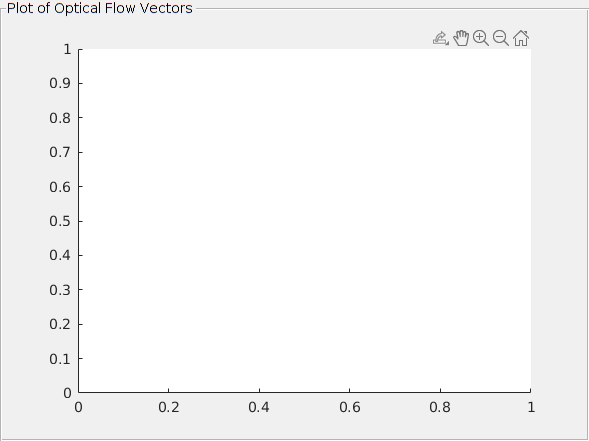

h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);

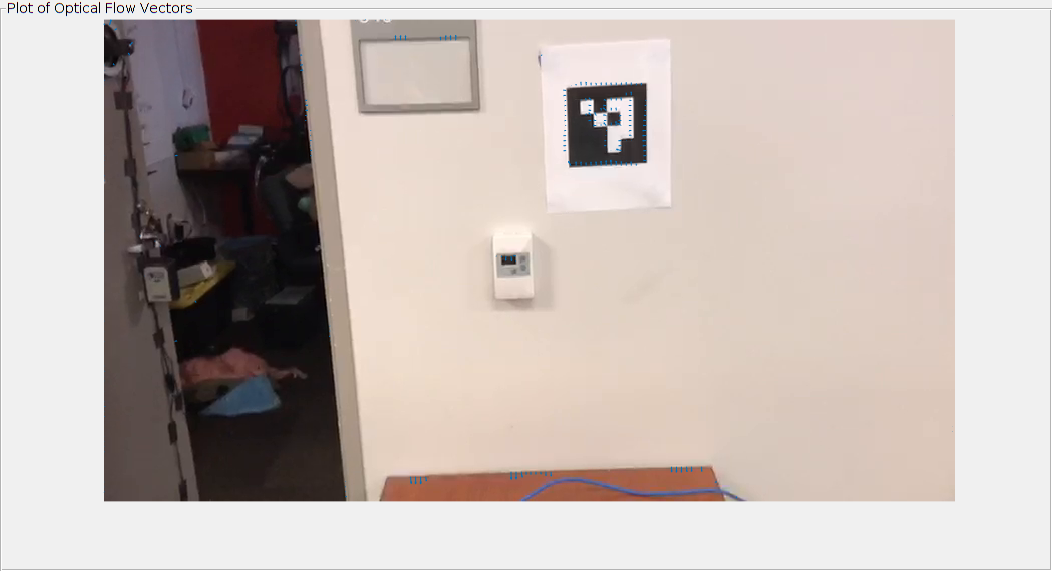

while hasFrame(vidReader)
    frameRGB = readFrame(vidReader);
    frameGray = im2gray(frameRGB);
    flow = estimateFlow(opticFlow,frameGray);
    imshow(frameRGB)
    hold on
    plot(flow,'DecimationFactor',[5 5],'ScaleFactor',10,'Parent',hPlot);
    hold off
    pause(10^-3)
end